%% 1.D(a) - LQR design for linear system
% The Constant values are imported in the workspace_data file as specified in the problem

%The A and B matrix values were obtained from our state space
%equation
%Substituting the values of constants in A and B, we get the following
A=[0 1 0 0 0 0;
    0 0 -(m1*g)/M 0 -(m2*g)/M 0;
    0 0 0 1 0 0;
    0 0 -((M+m1)*g)/(M*l1) 0 -(m2*g)/(M*l1) 0;
    0 0 0 0 0 1;
    0 0 -(m1*g)/(M*l2) 0 -(g*(M+m2))/(M*l2) 0]

A =          0    1.0000         0         0         0         0
         0         0   -0.9810         0   -0.9810         0
         0         0         0    1.0000         0         0
         0         0   -0.5395         0   -0.0491         0
         0         0         0         0         0    1.0000
         0         0   -0.0981         0   -1.0791         0



B=[0; 1/M; 0; 1/(M*l1); 0; 1/(M*l2)]

B = 1.0e-03 *

         0
    1.0000
         0
    0.0500
         0
    0.1000



Controllability= [B A*B A*A*B A*A*A*B A*A*A*A*B A*A*A*A*A*B]

Controllability = 1.0e-03 *

         0    1.0000         0   -0.1472         0    0.1419
    1.0000         0   -0.1472         0    0.1419         0
         0    0.0500         0   -0.0319         0    0.0227
    0.0500         0   -0.0319         0    0.0227         0
         0    0.1000         0   -0.1128         0    0.1249
    0.1000         0   -0.1128         0    0.1249         0


if (rank(Controllability)==6)
    disp("Rank of the controllabilty matrix matches order of A, Hence the system is controllable")
else
    disp("Rank of the controllabilty matrix does not match the order of A, Hence the system is uncontrollable")
end

Rank of the controllabilty matrix matches order of A, Hence the system is controllable


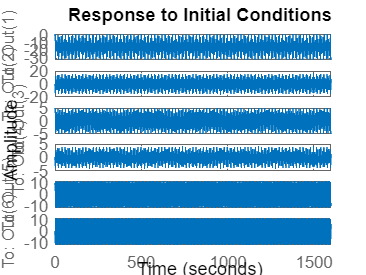

%the initial conditions are set as follows.
X_initial = [1;0;5;0;10;0]; 
% We assume the values of Q and R for the LQR Controller to check the performance. 
Q=[100 0 0 0 0 0;
   0 100 0 0 0 0;
   0 0 100 0 0 0;
   0 0 0 100 0 0;
   0 0 0 0 100 0;
   0 0 0 0 0 100];
R=0.002;
% Q and R values are a part of the cost function of the LQR controller  
% Q matrix defines the weights on the system states while the R matrix defines the weights on the control input of the cost function
% We assume: C is an identity matrix and D=0 i.e., Y=X (when C=I and D=0)

C_matrix = eye(6);
D_matrix = 0; 
system1 = ss(A,B,C_matrix,D_matrix);
% ss is the inbuilt MATLAB function used for
% calculating the state space representation of the system
figure
initial(system1,X_initial)
%MATLAB inbuilt function to check the initial response of the system
grid on  


[K_Gain_matrix, Pos_def_mat, Poles] = lqr(A,B,Q,R); %In-built MATLAB function for LQR Controllers
disp("The gain matrix is given as :")

The gain matrix is given as :


K_Gain_matrix

K_Gain_matrix =   223.6068  764.0782  -64.3470 -633.1536    2.0326 -311.2860


disp("The positive definite matrix for the LQR controller is given as")

The positive definite matrix for the LQR controller is given as


Pos_def_mat

Pos_def_mat = 1.0e+04 *

    0.0342    0.0534   -0.0283   -0.0836   -0.0139   -0.0448
    0.0534    0.1867   -0.0132   -0.3433   -0.0028   -0.1673
   -0.0283   -0.0132    1.8747    0.0351    0.0103   -0.0144
   -0.0836   -0.3433    0.0351    4.0587    0.0539    0.1374
   -0.0139   -0.0028    0.0103    0.0539    0.9021    0.0047
   -0.0448   -0.1673   -0.0144    0.1374    0.0047    0.9819


disp("The determinant of the positive definite matrix is : ")

The determinant of the positive definite matrix is : 


det(Pos_def_mat)

ans = 1.6295e+22

disp("The poles of the system are : ")

The poles of the system are : 


Poles

Poles =   -0.0126 + 0.7245i
  -0.0126 - 0.7245i
  -0.0222 + 1.0387i
  -0.0222 - 1.0387i
  -0.3159 + 0.3001i
  -0.3159 - 0.3001i


disp("Since the poles lie on the left hand plane, the system is Stable")

Since the poles lie on the left hand plane, the system is Stable


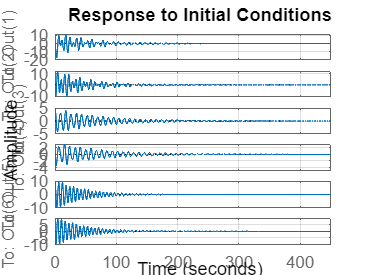

 
system_2 = ss(A-(B*K_Gain_matrix),B,C_matrix,D_matrix); %Using the K matrix to define ss
figure
initial(system_2,X_initial)
grid on